# **Plots**

clear
addpath('..\..\packages\cbrewer');

addpath('..\..\packages\alluvialflow');

if not(isfolder('..\plots'))
    mkdir('..\plots')
end
addpath(genpath('..\data\'))
addpath('..\plots')

# Figure 5

## PCA post-induction with end data

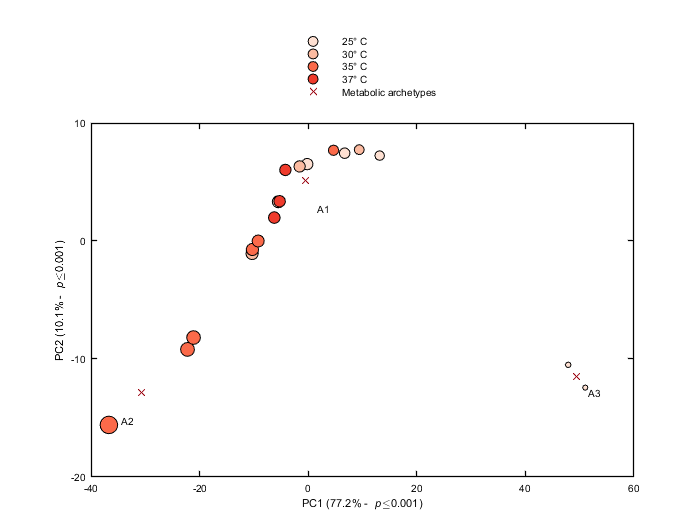

load end_pFBA_fluxes.mat
load AA_results_exploration_archetypes.mat
load PCA_permutation_test_exploration.mat
load exploration_cytotoxicities.mat
load DoE_data.mat

fluxes = fluxes(1:numel(exploration_cytotoxicities), :);
zcytotoxicities = (exploration_cytotoxicities - min(exploration_cytotoxicities)) ./ ...
    (max(exploration_cytotoxicities) - min(exploration_cytotoxicities));

[coeff,score,latent,tsquared,explained,mu] = pca(zscore(fluxes));
T_25_idx = DoE_data.exploration_data.T == 25;
T_30_idx = DoE_data.exploration_data.T == 30;
T_35_idx = DoE_data.exploration_data.T == 35;
T_37_idx = DoE_data.exploration_data.T == 37;

% colors
cb1 = cbrewer('seq', 'Reds', 8);

figure
hold on 
h1 = scatter(score(T_25_idx,1), score(T_25_idx,2), (10+100*zcytotoxicities(T_25_idx,1)), ...
    cb1(2,:), 'o', 'filled', 'MarkerEdgeColor', 'k');
h2 = scatter(score(T_30_idx,1), score(T_30_idx,2), (10+100*zcytotoxicities(T_30_idx,1)), ...
    cb1(3,:), 'o', 'filled', 'MarkerEdgeColor', 'k');
h3 = scatter(score(T_35_idx,1), score(T_35_idx,2), (10+100*zcytotoxicities(T_35_idx,1)), ...
    cb1(5,:), 'o', 'filled', 'MarkerEdgeColor', 'k');
h4 = scatter(score(T_37_idx,1), score(T_37_idx,2), (10+100*zcytotoxicities(T_37_idx,1)), ...
    cb1(6,:), 'o', 'filled', 'MarkerEdgeColor', 'k');
h5 = scatter(XC'*coeff(:,1), XC'*coeff(:,2), 22, cb1(8,:), 'x');
h6 = text(XC'*coeff(:,1)+[4.5;-1.5;4.5], XC'*coeff(:,2)-[3;3;2], {'A1', 'A2', 'A3'}, ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 6);
hold off
set(gca, 'LineWidth', 0.7, 'FontName', 'Arial', 'FontSize', 6, 'XColor', 'k', 'YColor', 'k')
set(gca, 'xlim', [-40, 60], 'ylim', [-20, 10], 'xtick', -40:20:60, 'ytick', -20:10:10)
xlabel(['PC1 (', num2str(round(explained(1), 1)), '% - \it p\rm\leq' num2str(p_lambdas(1)) ')'], 'FontSize', 8, 'FontName', 'Arial')
ylabel(['PC2 (', num2str(round(explained(2), 1)), '% - \it p\rm\leq' num2str(p_lambdas(2)) ')'], 'FontSize', 8, 'FontName', 'Arial')
l = legend({'25° C', '30° C', '35° C', '37° C', 'Metabolic archetypes'}, 'Location', 'northoutside', 'FontSize', 6);
set(l, 'Box', 'off');
box on

my_print('..\plots\PCA exploration', 3, 4, 'landscape')

## **Archetype pathway enrichment**

load AA_results_exploration_archetype_enrichment.mat

pathways = unique([enrichment_table{1}(2:end, 3); enrichment_table{2}(2:end, 3); enrichment_table{3}(2:end, 3)]);
pvalues = nan(length(pathways), 3);
[a, b] = ismember(pathways, enrichment_table{1}(:, 3));
pvalues(a, 1) = cell2mat(enrichment_table{1}(b(a), 2));
[a, b] = ismember(pathways, enrichment_table{2}(:, 3));
pvalues(a, 2) = cell2mat(enrichment_table{2}(b(a), 2));
[a, b] = ismember(pathways, enrichment_table{3}(:, 3));
pvalues(a, 3) = cell2mat(enrichment_table{3}(b(a), 2));
pvalues(pvalues < 10^-6) = 10^-6;
pvalues = round(pvalues, 2, 'significant');

h = heatmap({'A1','A2','A3'}, pathways, pvalues, ...
    'MissingDataLabel', 'No data', ...
    'CellLabelFormat', '%.1e', ...
    'FontSize', 6, 'FontName', 'Arial', ...
    'ColorScaling','log');

% color map
cmap = h.Colormap;
n = 50;               %// number of colors
R = [linspace(cmap(end, 1), 1, n) ones(1, 50-n)];  %// Red from 1 to 0
G = [linspace(cmap(end, 2), 1, n) ones(1, 50-n)];   %// Green all zero
B = [linspace(cmap(end, 3), 1, n) ones(1, 50-n)];  %// Blue from 0 to 1
h.Colormap = [R' G' B']

h =   HeatmapChart with properties:

        XData: {3×1 cell}
        YData: {32×1 cell}
    ColorData: [32×3 double]

  Show all properties


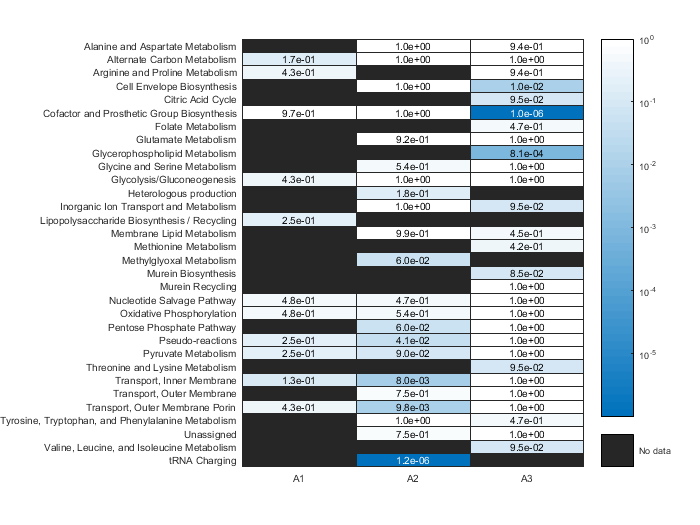


my_print('..\plots\AA enrichment exploration', 4.8, 5, 'landscape')

## **PLSCA variable relationship**

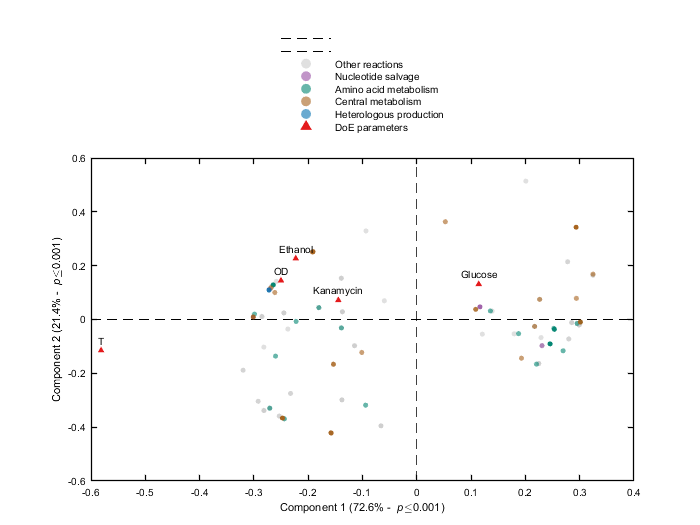

load end_pFBA_fluxes.mat
fluxes = fluxes(1:18, :);
all_rxns = rxns;
load PLSCA_results_exploration.mat

% take only factor scores for the positive components of the Escofier transform
fluxes_factor_scores = fluxes_factor_scores(length(fluxes_factor_scores)/2+1:end, :);
fluxes_BSRs = fluxes_BSRs(length(fluxes_BSRs)/2+1:end, :);
DoE_factor_scores = DoE_factor_scores(length(DoE_factor_scores)/2+1:end, :);
DoE_BSRs = DoE_BSRs(length(DoE_BSRs)/2+1:end, :);

% select variables with a significant score for either component 1 or 2
fluxes_factor_scores = fluxes_factor_scores(ismember(rxns, bootstrap_rxns), :);
fluxes_factor_scores = fluxes_factor_scores(or(abs(fluxes_BSRs(:, 1)) > 2, abs(fluxes_BSRs(:, 2)) > 2), :);
bootstrap_rxns = bootstrap_rxns(or(abs(fluxes_BSRs(:, 1)) > 2, abs(fluxes_BSRs(:, 2)) > 2));
DoE_factor_scores = DoE_factor_scores(ismember(DoE_variables', bootstrap_DoE_variables), :);
DoE_factor_scores = DoE_factor_scores(or(abs(DoE_BSRs(:, 1)) > 2, abs(DoE_BSRs(:, 2)) > 2), :);
bootstrap_DoE_variables = bootstrap_DoE_variables(or(abs(DoE_BSRs(:, 1)) > 2, abs(DoE_BSRs(:, 2)) > 2));

% get subSystems for bootstrap reactions
bootstrap_rxns = regexprep(bootstrap_rxns, '^v_', '');
[a, b] = ismember(bootstrap_rxns, all_rxns);
bootstrap_subSystems = subSystems(b(a));
central_rxns_idx = strcmp(bootstrap_subSystems, 'Citric Acid Cycle') | ...
    strcmp(bootstrap_subSystems, 'Glycolysis/Gluconeogenesis') | ...
    strcmp(bootstrap_subSystems, 'Oxidative Phosphorylation') | ...
    strcmp(bootstrap_subSystems, 'Pentose Phosphate Pathway');% | ...
    %strcmp(bootstrap_subSystems, 'Pyruvate Metabolism');
aa_rxns_idx = strcmp(bootstrap_subSystems, 'Alanine and Aspartate Metabolism') | ...
    strcmp(bootstrap_subSystems, 'Arginine and Proline Metabolism') | ...
    strcmp(bootstrap_subSystems, 'Cysteine Metabolism') | ...
    strcmp(bootstrap_subSystems, 'Glutamate Metabolism') | ...
    strcmp(bootstrap_subSystems, 'Glycine and Serine Metabolism') | ...
    strcmp(bootstrap_subSystems, 'Histidine Metabolism') | ...
    strcmp(bootstrap_subSystems, 'Methionine Metabolism') | ...
    strcmp(bootstrap_subSystems, 'Threonine and Lysine Metabolism') | ...
    strcmp(bootstrap_subSystems, 'Tyrosine, Tryptophan, and Phenylalanine Metabolism') | ...
    strcmp(bootstrap_subSystems, 'Valine, Leucine, and Isoleucine Metabolism');
nucleotide_rxns_idx = strcmp(bootstrap_subSystems, 'Nucleotide Salvage Pathway');
production_rxns_idx = strcmp(bootstrap_subSystems, 'Heterologous production');
other_rxns_idx = ~any([central_rxns_idx, aa_rxns_idx, nucleotide_rxns_idx, production_rxns_idx], 2);

% colors
cb1 = cbrewer('div', 'BrBG', 5);
cb2 = cbrewer('qual', 'Set1', 5);
cb3 = cbrewer('div', 'RdBu', 5);

figure
hold on
plot([-0.6, 0.4], [0, 0], '--k');
plot([0, 0], [-0.6, 0.6], '--k');
scatter(fluxes_factor_scores(other_rxns_idx, 1), fluxes_factor_scores(other_rxns_idx, 2), 10, [0.8, 0.8, 0.8], ...
    'filled', 'MarkerFaceAlpha', 0.6);
scatter(fluxes_factor_scores(nucleotide_rxns_idx, 1), fluxes_factor_scores(nucleotide_rxns_idx, 2), 10, cb2(4, :), ...
    'filled', 'MarkerFaceAlpha', 0.6);
scatter(fluxes_factor_scores(aa_rxns_idx, 1), fluxes_factor_scores(aa_rxns_idx, 2), 10, cb1(5, :), ...
    'filled', 'MarkerFaceAlpha', 0.6);
scatter(fluxes_factor_scores(central_rxns_idx, 1), fluxes_factor_scores(central_rxns_idx, 2), 10, cb1(1, :), ...
    'filled', 'MarkerFaceAlpha', 0.6);
scatter(fluxes_factor_scores(production_rxns_idx, 1), fluxes_factor_scores(production_rxns_idx, 2), 10, cb3(5, :), ...
    'filled', 'MarkerFaceAlpha', 0.6);
scatter(DoE_factor_scores(:, 1), DoE_factor_scores(:, 2), 12, cb2(1, :), 'filled', '^', 'MarkerFaceAlpha', 1);
text(DoE_factor_scores(:, 1), DoE_factor_scores(:, 2)+0.01, bootstrap_DoE_variables, ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center', 'FontSize', 6)
hold off

set(gca, 'LineWidth', 0.7, 'FontName', 'Arial', 'FontSize', 6, 'XColor', 'k', 'YColor', 'k')
xlabel(['Component 1 (', num2str(round(explained(1), 1)), '% - \it p\rm\leq' num2str(p_lambdas(1)) ')'], 'FontSize', 8)
ylabel(['Component 2 (', num2str(round(explained(2), 1)), '% - \it p\rm\leq' num2str(p_lambdas(2)) ')'], 'FontSize', 8)
l = legend({''; ''; 'Other reactions'; 'Nucleotide salvage'; 'Amino acid metabolism'; 'Central metabolism'; ...
    'Heterologous production'; 'DoE parameters'}, 'Location', 'northoutside', 'FontSize', 6);
set(l, 'Box', 'off');
box on

my_print('..\plots\PLSCA factor scores exploration', 3.5, 4, 'landscape')

## **PLSCA focus on ethanol, T and glucose**

load end_pFBA_fluxes.mat
fluxes = fluxes(1:18, :);
all_rxns = rxns;
load results\PLSCA_results_exploration.mat
load iEC1356_Bl21DE3.mat

% take only factor scores for the positive components of the Escofier transform
fluxes_factor_scores = fluxes_factor_scores(length(fluxes_factor_scores)/2+1:end, :);
fluxes_BSRs = fluxes_BSRs(length(fluxes_BSRs)/2+1:end, :);
DoE_factor_scores = DoE_factor_scores(length(DoE_factor_scores)/2+1:end, :);
DoE_BSRs = DoE_BSRs(length(DoE_BSRs)/2+1:end, :);

% select variables with a significant score for either component 1 or 2
fluxes_factor_scores = fluxes_factor_scores(ismember(rxns, bootstrap_rxns), :);
fluxes_factor_scores = fluxes_factor_scores(or(abs(fluxes_BSRs(:, 1)) > 2, abs(fluxes_BSRs(:, 2)) > 2), :);
bootstrap_rxns = bootstrap_rxns(or(abs(fluxes_BSRs(:, 1)) > 2, abs(fluxes_BSRs(:, 2)) > 2));
DoE_factor_scores = DoE_factor_scores(ismember(DoE_variables', bootstrap_DoE_variables), :);
DoE_factor_scores = DoE_factor_scores(or(abs(DoE_BSRs(:, 1)) > 2, abs(DoE_BSRs(:, 2)) > 2), :);
bootstrap_DoE_variables = bootstrap_DoE_variables(or(abs(DoE_BSRs(:, 1)) > 2, abs(DoE_BSRs(:, 2)) > 2));

% fix subsystem and reaction names
subSystems = strrep(subSystems, 'Pseudo-reactions', 'Boundary pseudo-reactions');
all_rxns = regexprep(all_rxns, '^v_', '');
bootstrap_rxns = regexprep(bootstrap_rxns, '^v_', '');

% reverse tempereature factor scores to see negative associations
DoE_factor_scores(strcmp(bootstrap_DoE_variables, 'T'), :) = -DoE_factor_scores(strcmp(bootstrap_DoE_variables, 'T'), :);

% calculate Euclidean distance between flux and DoE variables
D = pdist2(fluxes_factor_scores(:, 1:2), DoE_factor_scores(:, 1:2));

% adust rxn IDs
iEC1356_Bl21DE3.rxns = regexprep(iEC1356_Bl21DE3.rxns, '_copy1', '');


% rank reactions based on distance from ethanol
[sorted_D_ethanol, sort_idx] = sort(D(:, strcmp(bootstrap_DoE_variables, 'Ethanol')));
ethanol_rank_rxns = bootstrap_rxns(sort_idx);
[~, b] = ismember(ethanol_rank_rxns, all_rxns);
ethanol_rank_subSystems = subSystems(b);

% fetch rxn names of top-ranked rxns
ethanol_rank_rxns_cut = regexprep(ethanol_rank_rxns, '_f$', '');
ethanol_rank_rxns_cut = regexprep(ethanol_rank_rxns_cut, '_b$', '');
num_top_ranks = 12;
iEC1356_Bl21DE3.rxns = strrep(iEC1356_Bl21DE3.rxns, 'ASPt2pp_copy2', 'ASPt2pp');
[~, b] = ismember(ethanol_rank_rxns_cut(1:num_top_ranks), iEC1356_Bl21DE3.rxns);
ethanol_rank_rxnNames = iEC1356_Bl21DE3.rxnNames(b);

% add directionality information to rxn names
idx = endsWith(ethanol_rank_rxns(1:num_top_ranks), '_f');
suffix = cell(num_top_ranks, 1);
suffix(idx) = repmat({' (forward)'}, sum(idx), 1);
ethanol_rank_rxnNames = strcat(ethanol_rank_rxnNames, suffix);
idx = endsWith(ethanol_rank_rxns(1:num_top_ranks), '_b');
suffix = cell(num_top_ranks, 1);
suffix(idx) = repmat({' (backward)'}, sum(idx), 1);
ethanol_rank_rxnNames = strcat(ethanol_rank_rxnNames, suffix);


% rank reactions based on distance from T
[sorted_D_T, sort_idx] = sort(D(:, strcmp(bootstrap_DoE_variables, 'T')));
T_rank_rxns = bootstrap_rxns(sort_idx);
[~, b] = ismember(T_rank_rxns, all_rxns);
T_rank_subSystems = subSystems(b);

% fetch rxn names of top-ranked rxns
T_rank_rxns_cut = regexprep(T_rank_rxns, '_f$', '');
T_rank_rxns_cut = regexprep(T_rank_rxns_cut, '_b$', '');
num_top_ranks = 12;
[~, b] = ismember(T_rank_rxns_cut(1:num_top_ranks), iEC1356_Bl21DE3.rxns);
T_rank_rxnNames = iEC1356_Bl21DE3.rxnNames(b);

% add directionality information to rxn names
idx = endsWith(T_rank_rxns(1:num_top_ranks), '_f');
suffix = cell(num_top_ranks, 1);
suffix(idx) = repmat({' (forward)'}, sum(idx), 1);
T_rank_rxnNames = strcat(T_rank_rxnNames, suffix);
idx = endsWith(T_rank_rxns(1:num_top_ranks), '_b');
suffix = cell(num_top_ranks, 1);
suffix(idx) = repmat({' (backward)'}, sum(idx), 1);
T_rank_rxnNames = strcat(T_rank_rxnNames, suffix);


% rank reactions based on distance from glucose
[sorted_D_glucose, sort_idx] = sort(D(:, strcmp(bootstrap_DoE_variables, 'Glucose')));
glucose_rank_rxns = bootstrap_rxns(sort_idx);
[~, b] = ismember(glucose_rank_rxns, all_rxns);
glucose_rank_subSystems = subSystems(b);

% fetch rxn names of top-ranked rxns
glucose_rank_rxns_cut = regexprep(glucose_rank_rxns, '_f$', '');
glucose_rank_rxns_cut = regexprep(glucose_rank_rxns_cut, '_b$', '');
num_top_ranks = 12;
iEC1356_Bl21DE3.rxns = strrep(iEC1356_Bl21DE3.rxns, 'ASPt2pp_copy2', 'ASPt2pp');
[~, b] = ismember(glucose_rank_rxns_cut(1:num_top_ranks), iEC1356_Bl21DE3.rxns);
glucose_rank_rxnNames = iEC1356_Bl21DE3.rxnNames(b);

% add directionality information to rxn names
idx = endsWith(glucose_rank_rxns(1:num_top_ranks), '_f');
suffix = cell(num_top_ranks, 1);
suffix(idx) = repmat({' (forward)'}, sum(idx), 1);
glucose_rank_rxnNames = strcat(glucose_rank_rxnNames, suffix);
idx = endsWith(glucose_rank_rxns(1:num_top_ranks), '_b');
suffix = cell(num_top_ranks, 1);
suffix(idx) = repmat({' (backward)'}, sum(idx), 1);
glucose_rank_rxnNames = strcat(glucose_rank_rxnNames, suffix);



% set up plot variables
all_right_labels = unique([ethanol_rank_subSystems(1:num_top_ranks); ...
    T_rank_subSystems(1:num_top_ranks); ...
    glucose_rank_subSystems(1:num_top_ranks)], 'stable');
cb1 = cbrewer('qual', 'Set3', 15);

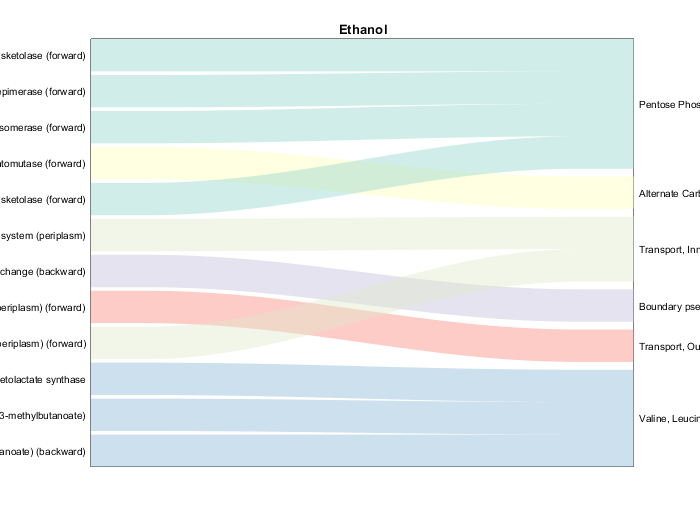


% plot rank for ethanol
left_labels = ethanol_rank_rxnNames;
right_labels = unique(ethanol_rank_subSystems(1:num_top_ranks), 'stable');
sankey_data = zeros(num_top_ranks, length(right_labels));
for i = 1:length(right_labels)
    sankey_data(strcmp(ethanol_rank_subSystems(1:num_top_ranks), right_labels(i)), i) = 1;
end
[~, b] = ismember(right_labels, all_right_labels);
colors = cb1(b, :);
h = alluvialflow(sankey_data, left_labels, right_labels, 'Ethanol', colors);

my_print('..\plots\Ethanol-associated reactions', 2, 3, 'landscape')

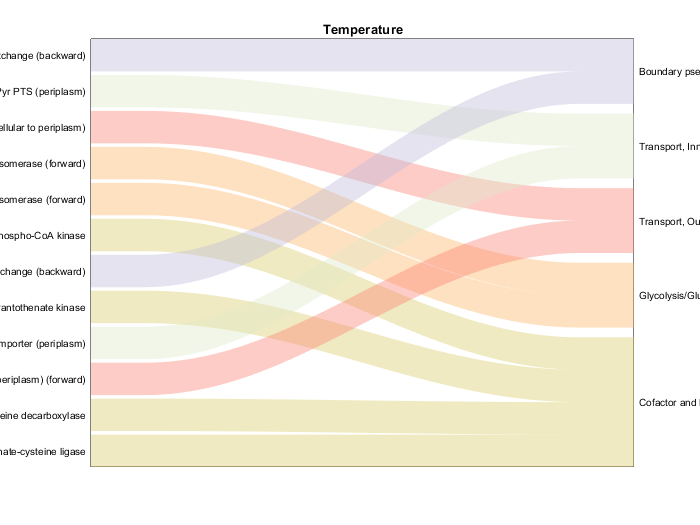


% plot rank for T
left_labels = T_rank_rxnNames;
right_labels = unique(T_rank_subSystems(1:num_top_ranks), 'stable');
sankey_data = zeros(num_top_ranks, length(right_labels));
for i = 1:length(right_labels)
    sankey_data(strcmp(T_rank_subSystems(1:num_top_ranks), right_labels(i)), i) = 1;
end
[~, b] = ismember(right_labels, all_right_labels);
colors = cb1(b, :);
h = alluvialflow(sankey_data, left_labels, right_labels, 'Temperature', colors);

my_print('..\plots\T-associated reactions', 2, 3, 'landscape')

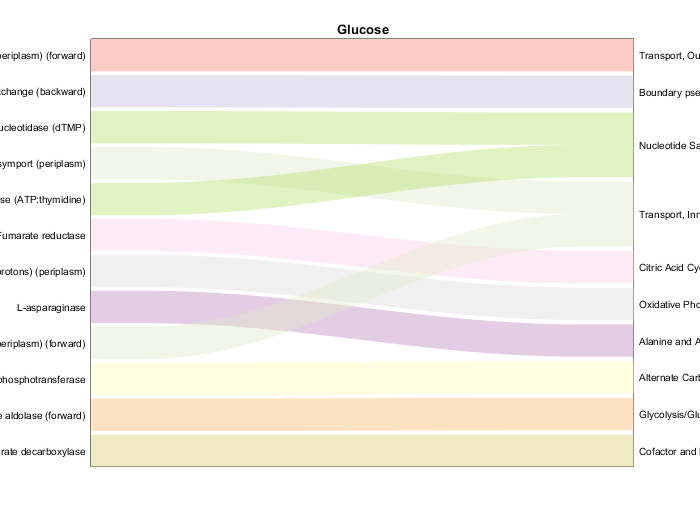


% plot rank for glucose
left_labels = glucose_rank_rxnNames;
right_labels = unique(glucose_rank_subSystems(1:num_top_ranks), 'stable');
sankey_data = zeros(num_top_ranks, length(right_labels));
for i = 1:length(right_labels)
    sankey_data(strcmp(glucose_rank_subSystems(1:num_top_ranks), right_labels(i)), i) = 1;
end
[~, b] = ismember(right_labels, all_right_labels);
colors = cb1(b, :);
h = alluvialflow(sankey_data, left_labels, right_labels, 'Glucose', colors);

my_print('..\plots\Glucose-associated reactions', 2, 3, 'landscape')

function my_print(name, width, height, orientation)
    fig = gcf;
    fig.PaperUnits = 'inches';
    fig.PaperSize = [width height];
    fig.PaperOrientation = orientation;
    print('-fillpage', name, '-dpdf', '-r600');
end